# Computing minimal cut sets

## Author: Susan Ghaderi, Luxembourg Centre for Systems Biomedicine 

## Reviewers: Sylvain Arreckx, Laurent Heirendt, Marouen Ben Guebila

## Francisco J. Planes, Department of Biomedical Engineering and Sciences, Tecnun, University of Navarra

## INTRODUCTION

During this tutorial, you will learn how to compute cut sets for paths/cycles/elementary modes with Berge algorithm [1-2].

Biologically, a cut set,$C$, is a set of reactions whose removal from a biochemical network leads to failure in a particular network target. For instance, if the target is the production of a metabolite $x$ , then the cut set will be the set of reactions that should be cut from the network in order to prevent the production of the metabolite  x . As a consequence, there is no feasible flux balance distribution to produce the metabolite $x$. In general, the target can be a set of reactions that make an elementary mode, a path, or a cycle. Mathematically, the set of all feasible fluxes $K$ defined in


$$K=\{ v\in  {R} ^n \mid Sv=0,v \geq 0, v\in Irr \}$$


is a polyhedral cone in $R^n$ where $Irr$ is a set of irreversible reaction. A set of reactions $C$ is a cut set for an objective $j\text{  }$ among reactions, if 


$$v_c=0 ~leads~to ~v_j=0~\forall~v\in K.$$


Consequently, a cut set  $C$ is *minimal* with respect to the target reaction $j \in Irr$  if no proper subset of $C$  is a cut set, which is a set with minimal number of reactions that can be removed with the assertion $v\in Irr ~\text{for all} ~v \in K$.

We introduce an interface to the software that enables the computation of the cut set for paths, cycles and elementary modes.

## MATERIALS

-  Please ensure that the COBRA Toolbox has been properly installed.

- *You should install CNA (CellNetAnalyzer) software and initialise it. CNA web site (with manual): *[https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html](https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html) 

## EQUIPMENT SETUP

Requirements for using CellNetAnalyzer are:

- MATLAB Version 7.5 (Release 18) or higher.

- some functions require an LP or (M)ILP solver; CNA supports the optimization toolbox of MATLAB, GLPKMEX, and CPLEX).

- More information can be found on: [https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html](https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html) where also a how-to tutorial on CellNetAnalyzer is provided.

## PROCEDURE 

*Before you start with these codes, you should place the CellNetAnalyzer folder in the directory where you are working and initialise CNA software by the following commands*

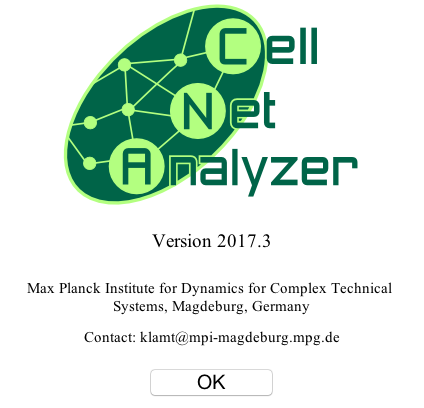

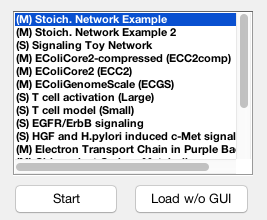

% Add path to Cell Net Analyzer
CNAPath = 'CellNetAnalyzer';
addpath(genpath(CNAPath));
startcna

## Computing minimal cut set

The mandatory input in minimal cut set code is a set `E` that can be paths, cycles or elementary-modes that you are going to compute its minimal cut set. 

% define the model
global CBTDIR
addpath([CBTDIR filesep 'tutorials' filesep 'additionalTutorials' filesep 'minimalCutSets'])
load('E.mat')% the set of two elementary modes (E(1,:) and E(2,:)) which we are going to compute its minimal cut set.
C = minimalCutSets(E(1,:))

 
Computing minimal cut sets / hypergraph transversal
***************************************************
Found and removed 2 elements not contained in any mode.
 
Number of elements that cannot be deleted due to side constraints : 0
 
Number of admissable cut sets with 1 element : 3
 
0 equivalent elements found and removed
0 remaining elements
 
Ready! Computation time: 0.07 sec
Longest list merge: 0.
Compressed MCS list length: 3.
 
Final result: 3 cut sets.


C =    1   0   0   0   0
   0   1   0   0   0
   0   0   0   0   1


C =    1   0   0   0   0
   0   1   0   0   0
   0   0   0   0   1


The set of cut sets for elementary mode 2 is

C = minimalCutSets(E(2,:))

 
Computing minimal cut sets / hypergraph transversal
***************************************************
Found and removed 2 elements not contained in any mode.
 
Number of elements that cannot be deleted due to side constraints : 0
 
Number of admissable cut sets with 1 element : 3
 
0 equivalent elements found and removed
0 remaining elements
 
Ready! Computation time: 0.01 sec
Longest list merge: 0.
Compressed MCS list length: 3.
 
Final result: 3 cut sets.


C =    0   0   1   0   0
   0   0   0   1   0
   0   0   0   0   1


C =    0   0   1   0   0
   0   0   0   1   0
   0   0   0   0   1


## INPUT

The neccessary input for computing minimal cut set of a set is `targets.`

  `targets`: a binary matrix that row-wise contains the target paths/cycles/elementary modes; a '1' in the i-th row and j-th column in targets indicates participation of element (reaction) j in mode i;

## OPTIONAL INPUTS:

-    `mcsmax`:      maximal size of cutsets to be calculated; must be a value grater than 0; Inf means no size limit (default: Inf)

-     `names`:       a char matrix; its rows are names corresponding to the columns of 'targets'; used for diagnostics in preprocessing (default:[]; the matrix is then constructed with 'I1,',I2',....)

-     `sets2save`:   (default: []) struct array with sets of (desired) modes/paths/cycles that should be preserved (not be involved in the cut sets computed). It should have the following fields

                 * sets2save(k).tabl2save = k-th matrix containing row-wise 'desired' sets (desired paths/cycles/ modes) that should not be hit by the cut sets to be computed and be saved. A '1' in the i-th row and j-th column of sets2save(k) indicates the participation of element j in mode i in set k of desired modes. These matrices must have the same number of columns (reactions) as 'targets'.

               * sets2save(k).min2save = specifies the minimum number of desired paths/cycles/modes in sets2save(k).tabl2save that should be preserved by the cut sets computed.

-  `earlycheck`:   whether the test checking for the fulfillment of constraints in sets2save should be carried out during (1) or after (0) computation of cut sets [default: 1; makes only sense in combination with sets2save]

##  OUTPUT:

   `C`:     matrix that contains the (constrained) cutsets row-wise; a '1' means that the reaction/interaction  is part of the cutset, 0 means the element/reaction/interaction is not involved. Each cutset hits all modes stored in "targets" but if sets2save not be empty (sets2save contains the modes that we do not want to be hit by cutset) then it does not hit at least a number of modes equal to "sets2save(k).min2save" in the matrix "sets2save(k).tabl2save".

## TIMING

The running time of this code is dependent on the size of the model and may take long (from 10 seconds to few hours). In addition to the running time you should consider between 60 seconds for start-up CellNetAnalyzer software.

## ANTICIPATED RESULTS

The anticipated results are the minimal cut set of every set which is as an input.

## REFERENCES

[1] Klamt. S. and Gilles ED. Minimal cut sets in biochemical reaction networks. Bioinformatics. 20, 226–234 (2004).

[2] Berge. C.  Hypergraphs, ser.North holland Mathematical Library. Elsiver Science Publishers B. V. 45, (1989).